# Grasp the cylinder from the side

## First

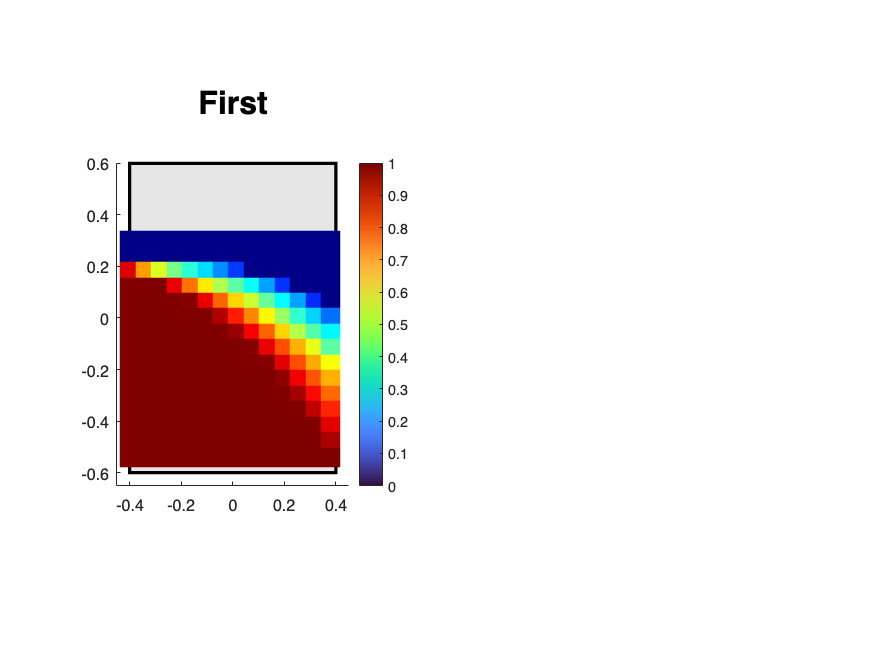

%clc; clear; close all;

data_pick_1 = importdata('data/1.txt');
data = data_pick_1;

x = data(:,1);
y = data(:,2);
z = data(:,3);

% convert array to mumber between 0-1 check for other method
z = mat2gray(z,[min(z) max(z)]); 

h1 = subplot(1,2,1);

hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);

hold off
colorbar
%grid on
shading interp
axis equal
view(0, 90);
title({'First',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])

## Second

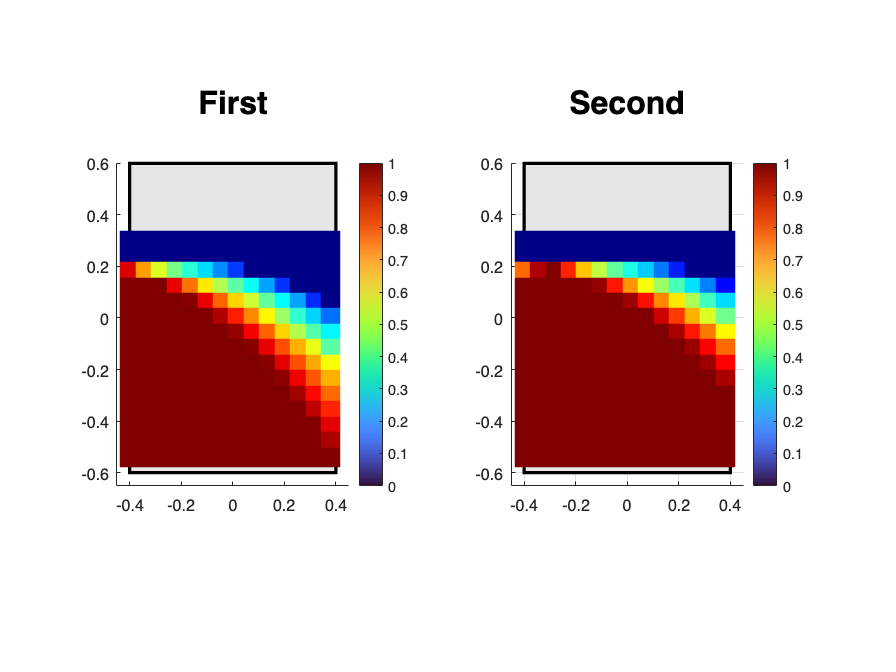

data_pick_2 = importdata('data/2.txt');
data = data_pick_2;

x = data(:,1); 
y = data(:,2);
z = data(:,3);

% convert array to mumber between 0-1 check for other method
z = mat2gray(z,[min(z) max(z)]); 

h2 = subplot(1,2,2);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

%figure('Name','Reachability Analysis','Position', [10 10 900 600])

colormap("turbo")

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90); % azimuth elevation
title({'Second',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])


% base_pos_indx = find(max(z)==z)
% base_pos = [x(base_pos_indx) y(base_pos_indx) 0.150]

## Third

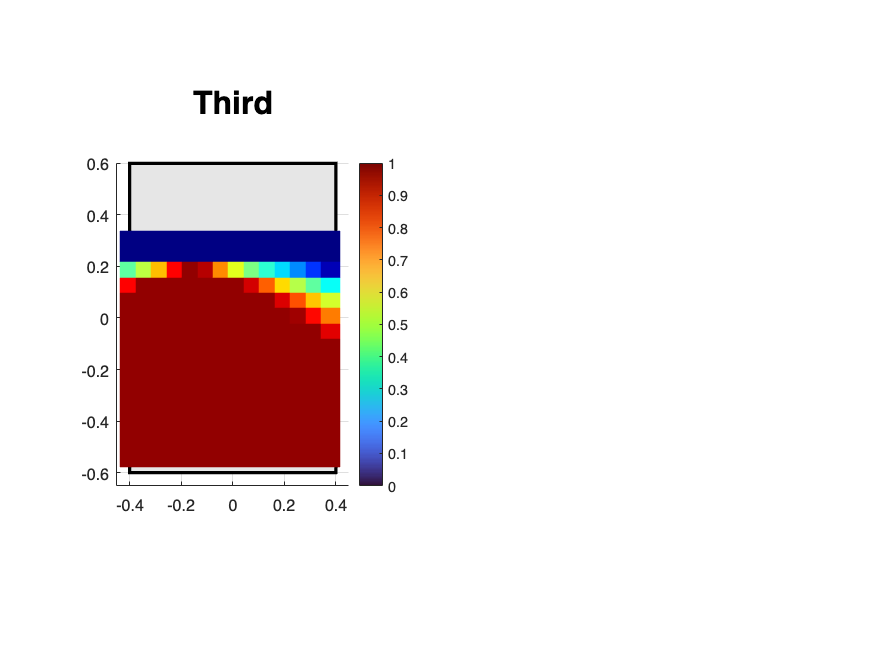

clc; clear; close all;

data_pick_3 = importdata('data/3.txt');

data = data_pick_3;

x = data(:,1);
y = data(:,2); 
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]);

h1 = subplot(1,2,1);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);


rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90); % azimuth elevation
title({'Third',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])


% base_pos_indx = find(max(z)==z)
% base_pos = [x(base_pos_indx) y(base_pos_indx) 0.150]

## Fourth

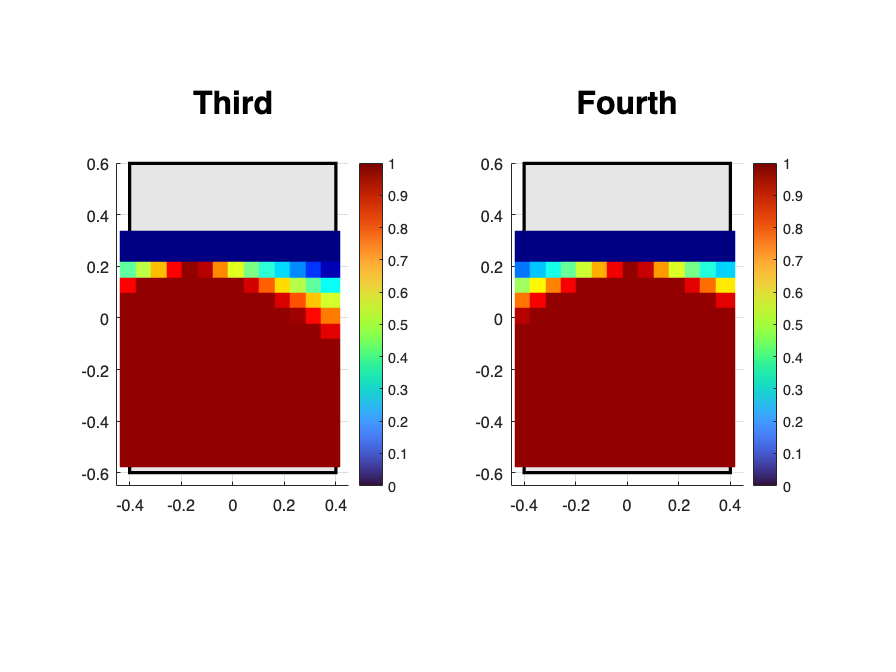


data_pick_4 = importdata('data/4.txt');
data = data_pick_4;

x = data(:,1);
y = data(:,2);
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]); 

%figure(2);
%stem3(x,y,z,"filled")
h2 = subplot(1,2,2);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

%surf(X, Y, Z);

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title({'Fourth',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])

## Fifth

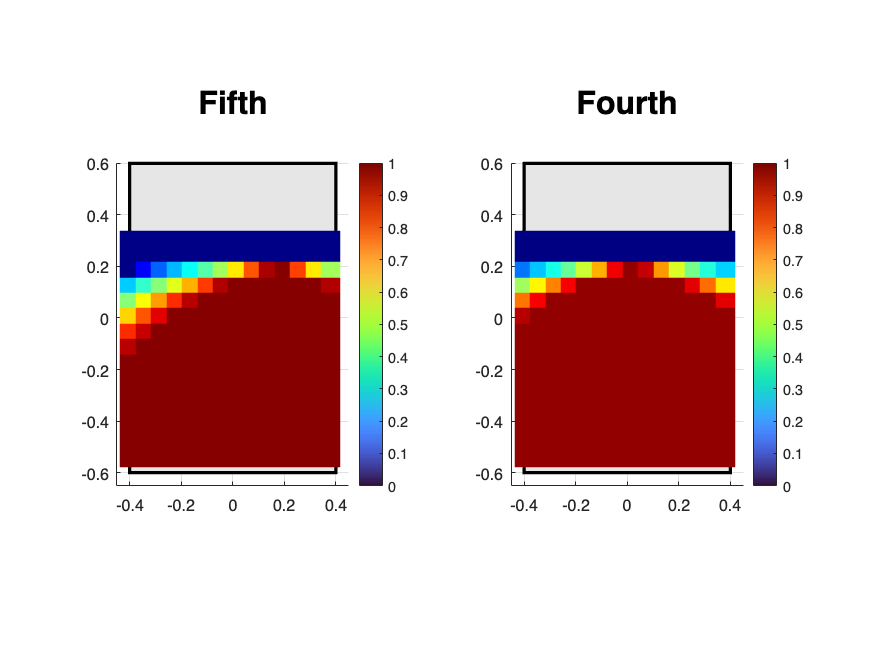


data_pick_5 = importdata('data/5.txt');
data = data_pick_5;

x = data(:,1);
y = data(:,2);
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]); 

%figure(2);
%stem3(x,y,z,"filled")
h1 = subplot(1,2,1);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

%surf(X, Y, Z);

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title({'Fifth',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])

## Sixth

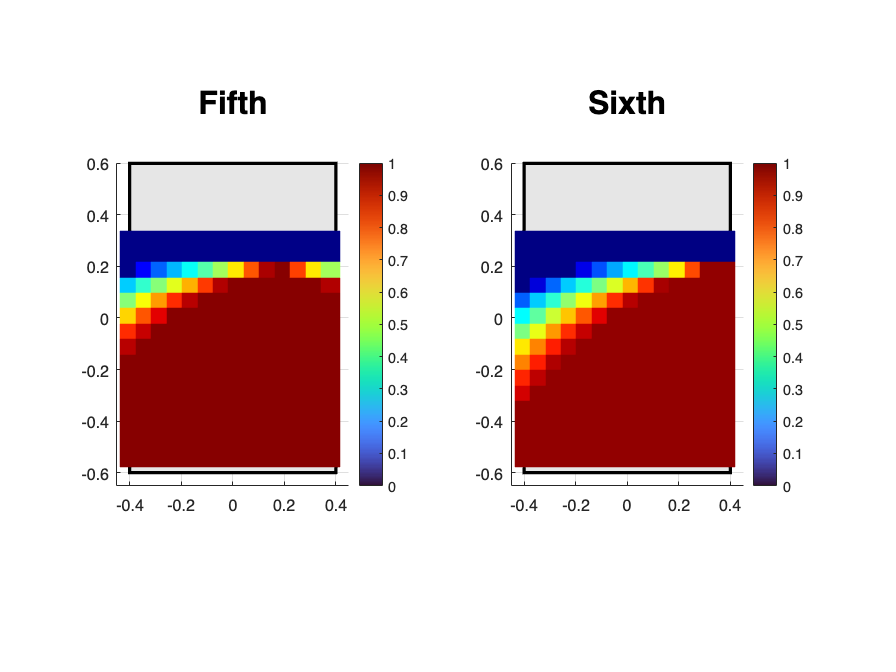


data_pick_6 = importdata('data/6.txt');
data = data_pick_6;

x = data(:,1);
y = data(:,2);
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]); 

%figure(2);
%stem3(x,y,z,"filled")
h2 = subplot(1,2,2);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

%surf(X, Y, Z);

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title({'Sixth',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])

## Seventh

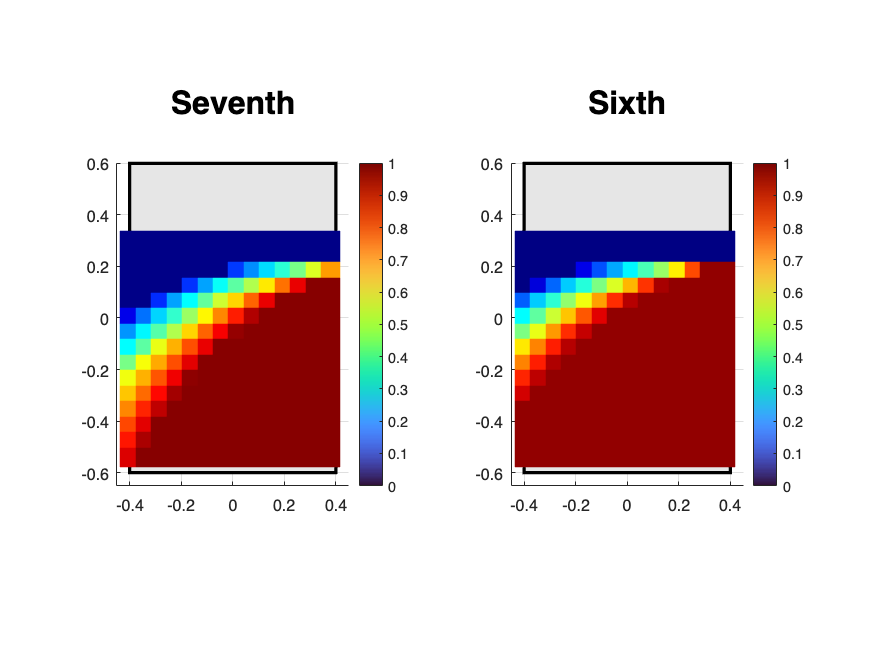


data_pick_7 = importdata('data/7.txt');
data = data_pick_7;

x = data(:,1);
y = data(:,2);
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]); 

%figure(2);
%stem3(x,y,z,"filled")
h1 = subplot(1,2,1);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

%surf(X, Y, Z);

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title({'Seventh',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])

## Place right

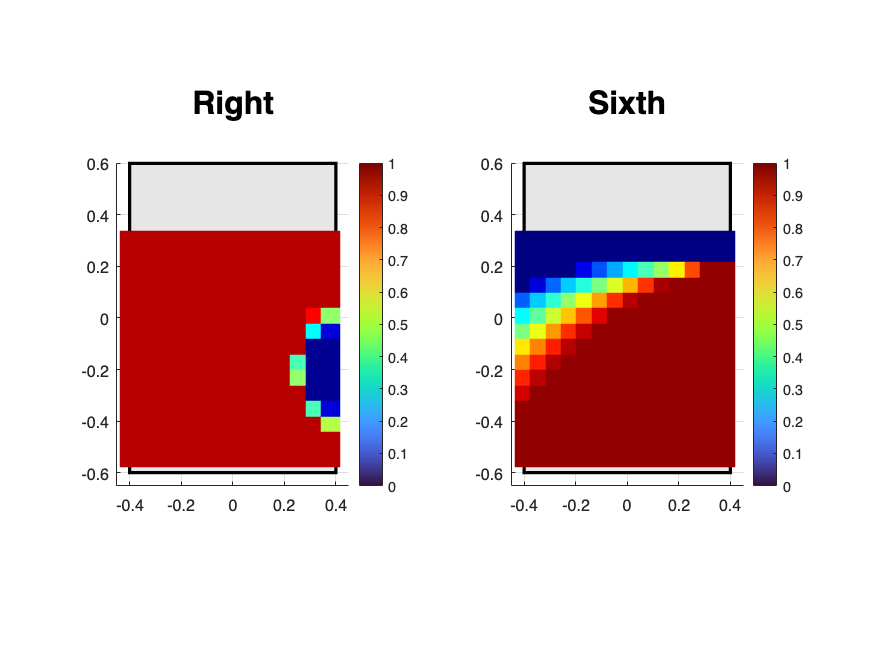


data_pick_right = importdata('data/right.txt');
data = data_pick_right;

x = data(:,1);
y = data(:,2);
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]); 

%figure(2);
%stem3(x,y,z,"filled")
h1 = subplot(1,2,1);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

%surf(X, Y, Z);

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title({'Right',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])

## Place left

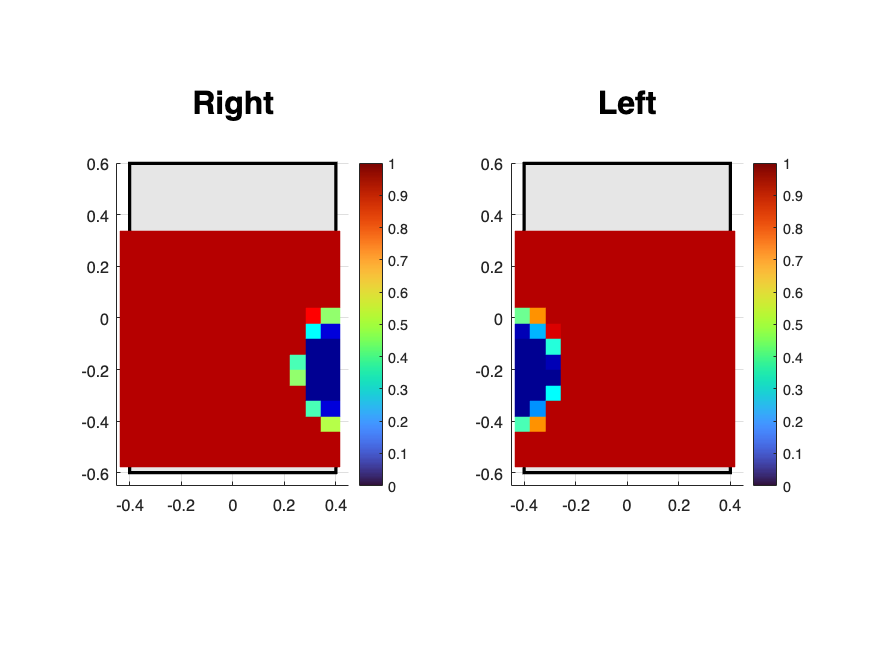


data_pick_left = importdata('data/left.txt');
data = data_pick_left;

x = data(:,1);
y = data(:,2);
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]); 

%figure(2);
%stem3(x,y,z,"filled")
h2 = subplot(1,2,2);

%grid on
hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

colormap("turbo")

%surf(X, Y, Z);

sz = 250;
cmap = jet(max(round(data(:,3)))+1);
c = cmap(round(data(:,3))+1,:);

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2);
scatter(data(:,1), data(:,2),sz,c,'filled','square')
xlabel('', 'FontSize', 14)
ylabel('', 'FontSize', 14)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title({'Left',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])

## Surface plot side complete

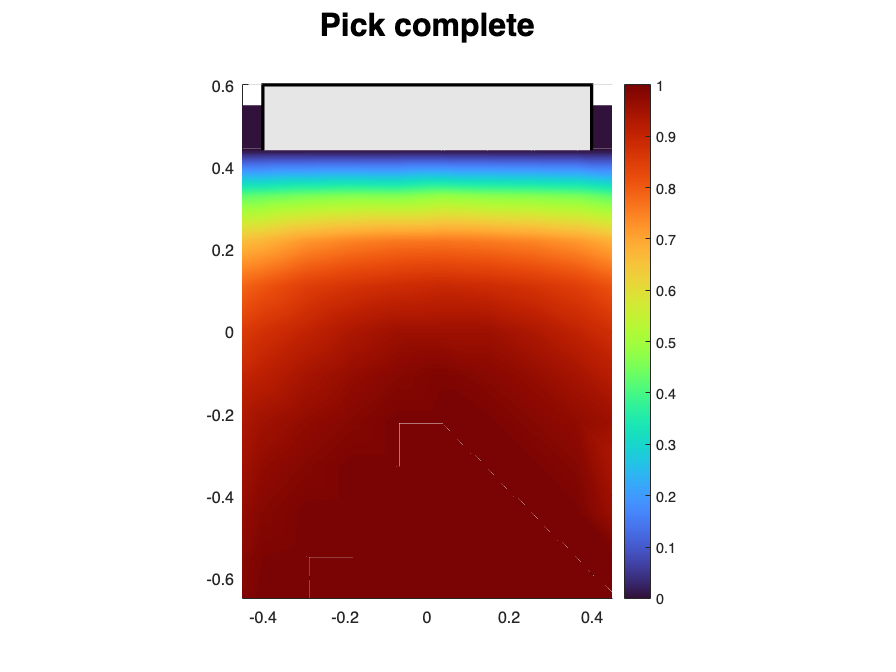

clc; clear; close all;

data_pick_1 = importdata('data/1.txt');
data_pick_2 = importdata('data/2.txt');
data_pick_3 = importdata('data/3.txt');
data_pick_4 = importdata('data/4.txt');
data_pick_5 = importdata('data/5.txt');
data_pick_6 = importdata('data/6.txt');
data_pick_7 = importdata('data/7.txt');
data_pick_left = importdata('data/left.txt');
data_pick_right = importdata('data/right.txt');

data = data_pick_1 + data_pick_2 + data_pick_3 + data_pick_4+data_pick_5+data_pick_6+data_pick_7+data_pick_left+data_pick_right*3;

x = data(:,1)./6;
y = data(:,2)./6; 
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]);

%h1 = subplot(1,2,1);


hold on
cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

tablex = [-0.4 0.4 0.4 -0.4];
tabley = [-0.6 -0.6 0.6 0.6];

%figure('Name','Reachability Analysis','Position', [10 10 900 600])

%figure('Name','Reachability Analysis','Position', [10 10 900 600])

surf(X, Y, Z);


colormap("turbo")

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
% scatter3([-0.28], [0.06], [2],800,[1,1,1],'x','Linewidth',2)
% scatter3([-0.28], [0.06], [2],800,[1,1,1],'o','LineWidth',4)
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title({'Pick complete',' '},'FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])




%base_pos_indx = find(max(z)==z)
%base_pos = [x(base_pos_indx) y(base_pos_indx) 0.150]



data_pick_1 = importdata('data/1.txt');
data_pick_2 = importdata('data/2.txt');
data_pick_3 = importdata('data/3.txt');
data_pick_4 = importdata('data/4.txt');
data_pick_5 = importdata('data/5.txt');
data_pick_6 = importdata('data/6.txt');
data_pick_7 = importdata('data/7.txt');
data_pick_left = importdata('data/left.txt');
data_pick_right = importdata('data/right.txt');

data = data_pick_1 + data_pick_2 + data_pick_3 + data_pick_4+data_pick_5+data_pick_6+data_pick_7+data_pick_left+data_pick_right*3;

x = data(:,1)./6;
y = data(:,2)./6; 
z = data(:,3);

z = mat2gray(z,[min(z) max(z)]);

%h2 = subplot(1,2,2);

%figure('Name','Reachability Analysis','Position', [10 10 900 600])


hold on

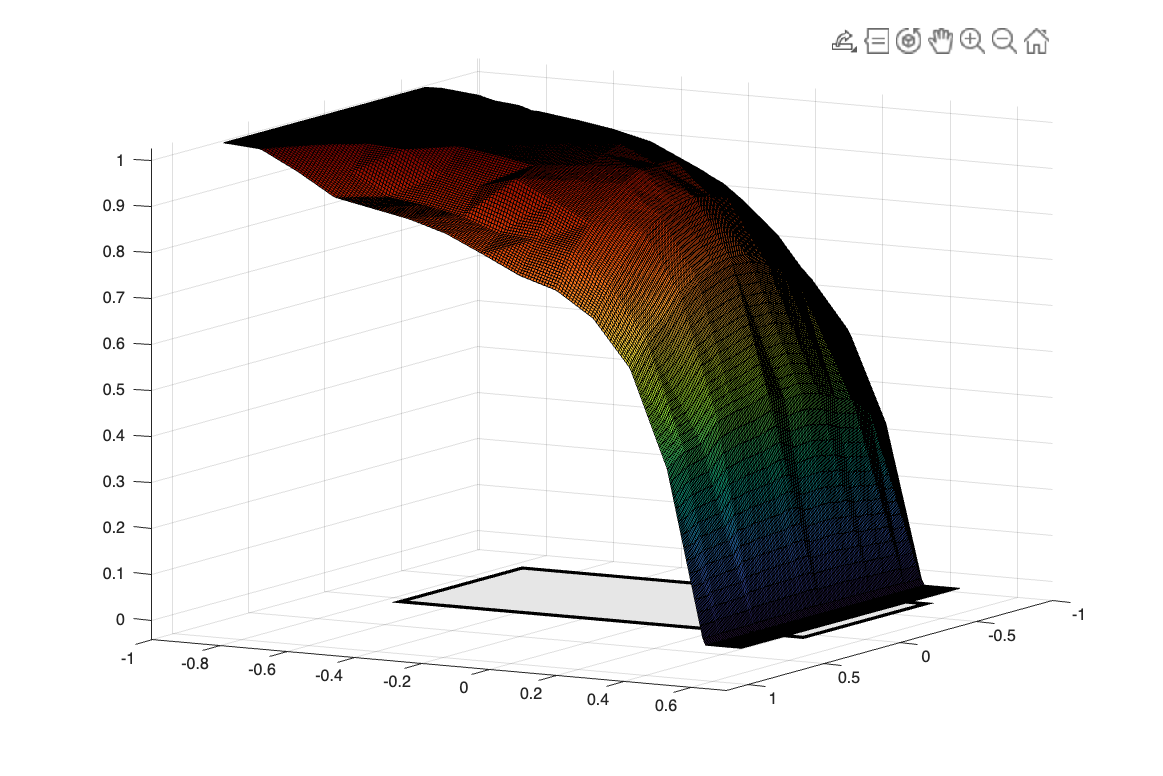

cx = linspace(min(x), max(x), 190);
cy = linspace(min(y), max(y), 190);
[X,Y] = meshgrid(cx, cy);
Z = griddata(x,y,z,X,Y);

tablex = [-0.4 0.4 0.4 -0.4];
tabley = [-0.6 -0.6 0.6 0.6];

figure('Name','Reachability Analysis','Position', [10 10 900 600])

surf(X, Y, Z);

colormap("turbo")

rectangle('Position',[-0.4 0.31 0.8 0.29],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
%rectangle('Position',[0.2 -0.6 0.2 0.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)
rectangle('Position',[-0.4 -0.6 0.8 1.2],'FaceColor',[0.9 0.9 0.9],'EdgeColor','k', 'LineWidth',2)

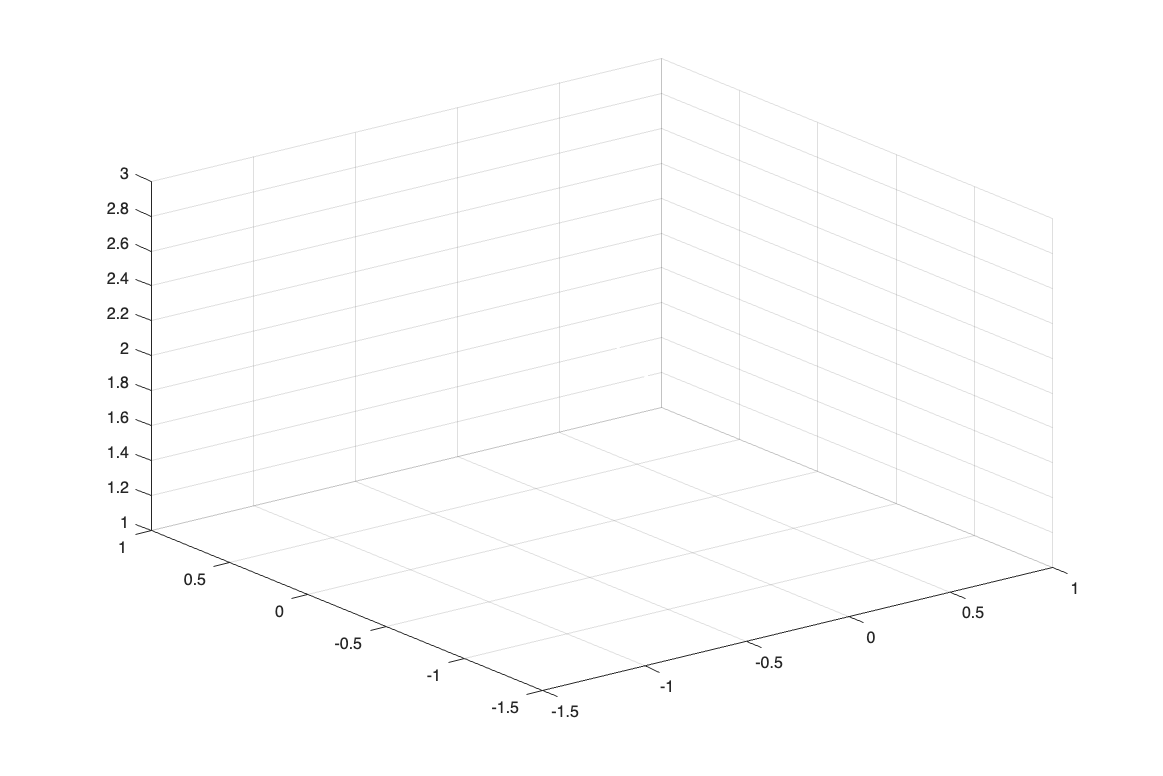

%cylinderCircle([-0.34],[0.54],0.05);
%cylinderCircle([0],[0.54],0.05);
%cylinderCircle([0.34],[0.54],0.05);
%cylinderCircle([0.30],[-0.5],0.05);
%%% Before Place positions
% scatter3([-0.06], [-0.18], [2],800,[1,1,1],'x','Linewidth',2)
% scatter3([-0.06], [-0.18], [2],800,[1,1,1],'o','LineWidth',4)
%%% After Place positions
scatter3([-0.0733], [-0.22], [2],800,[1,1,1],'x','Linewidth',2)

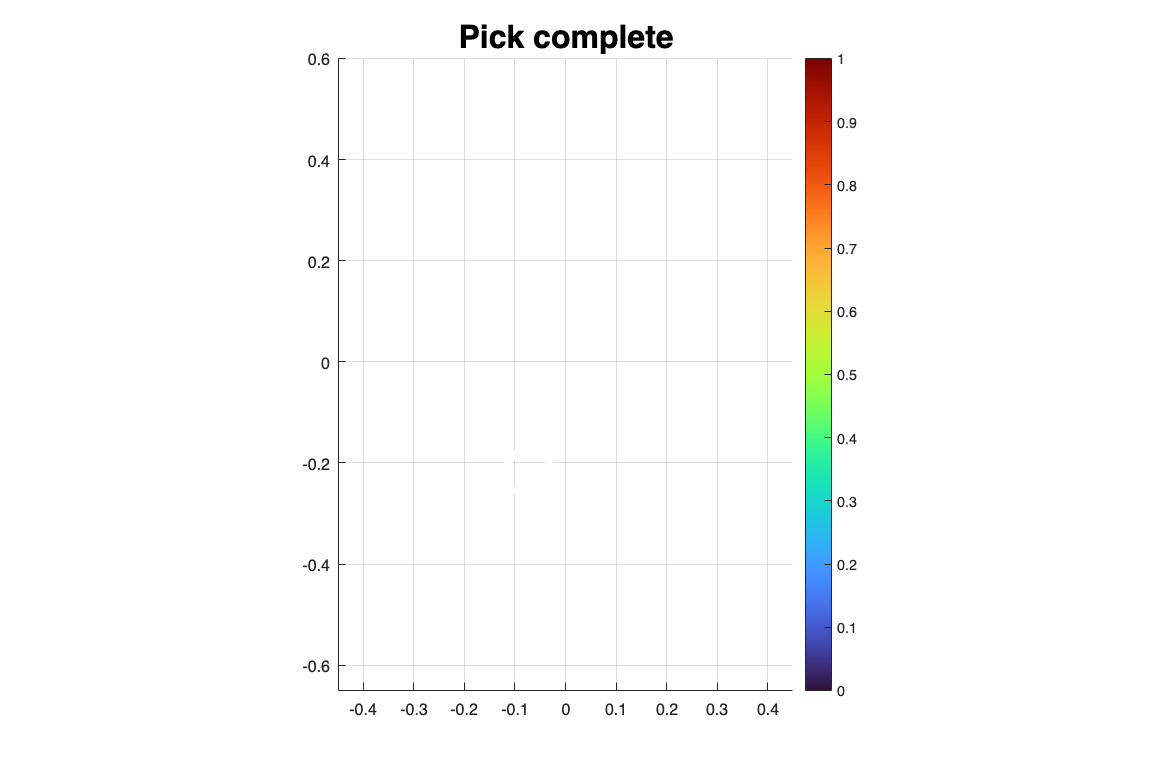

scatter3([-0.0733], [-0.22], [2],800,[1,1,1],'o','LineWidth',4)
hold off
colorbar
grid on
shading interp
axis equal
view(0, 90);
title('Pick complete','FontSize',20)
xlim([-0.45 0.45])
ylim([-0.65 0.60])




% base_pos_indx = find(max(z)==z)
% base_pos = [x(base_pos_indx) y(base_pos_indx) 0.150]

% Find the index of the maximum value in z
[~, base_pos_indx] = max(z);  % This will return only one index

% Now use this index to find the corresponding x and y values
base_pos = [x(base_pos_indx) y(base_pos_indx) 0.150]

base_pos =    -0.0733   -0.2200    0.1500


function h = cylinderCircle(x,y,r)
    d = r*2;
    px = x-r;
    py = y-r;
    h = rectangle('Position',[px py d d],'Curvature',[1,1],'FaceColor',[0.5 0.5 0.5]);
    daspect([1,1,1])
end